# Create a Table from a Cell Array

This example shows how to use a cell array to create a table that displays data of several different data types.

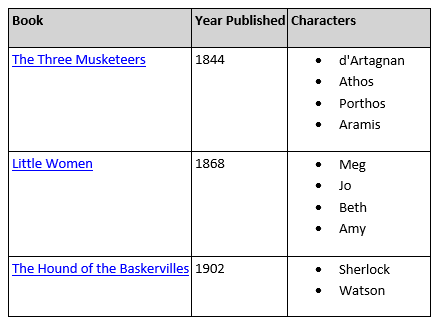

#### Document and Style Setup

The following code sets up a document and table styles to be used to format the example tables.

Import the DOM package so you do not have to use long, fully-qualified class names.

import mlreportgen.dom.*

Create and open a document. To create a PDF document, change the output type from `docx` to `pdf`. To create an HTML document, change `docx` to `html` or `html-file` for a multi-file or single-file document, respectively.

d = Document("mydoc","docx");
open(d);

Define styles for the table and header section of the table.

tableStyles = { ColSep("solid"), ...
                RowSep("solid"), ...
                Border("solid") };
            
tableHeaderStyles = { BackgroundColor("lightgray"), ...
                      Bold(true) };

#### Table Creation

Use a cell array in a table constructor to create a table from data with more than one data type. The cell array can contain doubles, strings, character vectors, DOM objects, and other arrays. This example uses a formal table, which is a table that has a body section and optional header and footer sections.

Define labels to display in the table header. The header labels are strings, so they are stored in a string array instead of a cell array.

headerLabels = ["Book", "Year Published", "Characters"];

Define data to display in the table body. The table data includes external links, numbers, and string arrays, so it is contained in a cell array.

book1 = ExternalLink("https://en.wikipedia.org/wiki/The_Three_Musketeers", ...
                     "The Three Musketeers");
book2 = ExternalLink("https://en.wikipedia.org/wiki/Little_Women", ...
                     "Little Women");
book3 = ExternalLink("https://en.wikipedia.org/wiki/The_Hound_of_the_Baskervilles", ...
                     "The Hound of the Baskervilles");

books = {book1; book2; book3};

yearPublished = {1844; 1868; 1902};

characters = { ["d'Artagnan", "Athos", "Porthos", "Aramis"]; ...
               ["Meg", "Jo", "Beth", "Amy"]; ...
               ["Sherlock", "Watson"] };

tableData = [books, yearPublished, characters]

Create a table containing the header labels and table data. The single-row string arrays in the table data are converted to DOM `UnorderedList` objects when the table is constructed.

cellTbl = FormalTable(headerLabels,tableData);

Set the style of the table and table header to the previously defined styles. Set the inner margin of the table entries so that table entry content is separated from the table entry borders by a space of two points. Append the table to the document.

cellTbl.Style = [cellTbl.Style, tableStyles];
cellTbl.Header.Style = [cellTbl.Header.Style, tableHeaderStyles];
cellTbl.TableEntriesInnerMargin = "2pt";
append(d,cellTbl);

Close and view the document.

close(d);
rptview(d);

*Copyright 2019 The MathWorks, Inc.*